# **Molecular representations and molecular descriptors**

## SMILES strings

The simplified molecular input line-entry system (SMILES) is a specification in the form of a line notation for describing the structure of one or more molecules, using short ASCII strings. SMILES strings can be imported by most molecule editors for conversion back into two-dimensional drawings or three-dimensional models of the molecules.

In brief (Figure 1)

- Atoms are represented by their atomic symbols, with the possibility to omit H; 

- Single, double, triple and aromatic bonds can be represented with the following symbols: “−”, “=”, “#”, and “:”, respectively. Single bonds can be omitted.

- Branches are specified by enclosures in parentheses; 

- Cyclic structures are represented by breaking one single or aromatic bond in each ring and starting from one of the ring atoms. Ring “opening”/”closure” bonds are then indicated by a digit immediately following the atomic symbol at each ring closure. Aromaticity on carbon atoms can be written with lower-case letters or by alternating single and double bonds (Kekulé notation). For instance, benzene can be both written as “c1ccccc1” and “C1=CC=CC=C1”;

- Local chirality can be specified using the symbols “/” and “\”. For instance, E- and Z-1,2-difluoroethene can be written as F/C=C/F and F/C=C\F, respectively. Additionally, tetrahedral centers are often indicated using “@” (or “@@”), following the atomic symbol of the chiral atom. “@” indicates that  the listed neighbors are arranged anticlockwise, while “@@” that they appear in a clockwise order. 

- The chosen atom order for generating the SMILES does not affect the encoded 2D structure. However, several types of standardized (also known as canonicalized) SMILES generation procedures exist.

You can find a summary of SMILES theory here: [https://www.daylight.com/dayhtml/doc/theory/theory.smiles.html](https://www.daylight.com/dayhtml/doc/theory/theory.smiles.html) 

#### 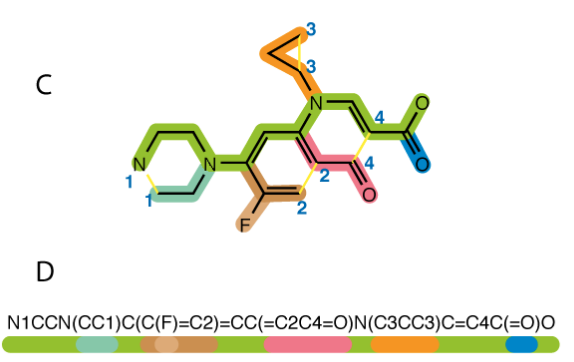

**Figure 1. **Example of the calculation of a SMILES string. Image from https://chejunkie.com/knowledge-base/convert-cas-registry-number-other/.

### SMILES strings: exercise 1

Which of the following molecular depictions corresponds to the reported SMILES string?

SMILES: 

A. 

SMILES: C1=CC(=CC(=C1)Br)OC(F)(F)F

""

ans = ""

### SMILES strings: exercise 2

## Molecular descriptors

In this part of the notebook, we will do some basic exercises on molecular descriptors and molecular similarity calculation. 

### Real-valued descriptors

#### Exercise 1

Calculate molecular descriptors for two molecules, expressed as SMILES strings:

Molecule 1:

SMILES string: "ClC(C)CC1=CC=C(C=C1)C(C)C(=O)O"

Molecule 2:

SMILES string: " "

Complete the code below, to compute the following descriptors:

- "nDB": number of double bonds

- "nO": number of oxygens

- "nCl": number of Chlorine atoms

- "nC": number of Carbon atoms

Tip!

`    strfind(string,refstring) `

finds the occurrence of `refstring `in `string`. 

Type `help strfind` to know more!

**Complete now the code below:**

smiles = 'ClC(C)CC1=CC=C(C=C1)C(C)C(=O)O';

nDB = []; % number of double bonds
nO = []; % number of oxygen atoms
nCl = [];  % number of chlorine atoms
nC = []; % number of carbon atoms

**Now to the next molecule:**

smiles = '';

nDB = []; % number of double bonds
nO = []; % number of oxygen atoms
nCl = [];  % number of chlorine atoms
nC = []; % number of carbon atoms

Attention: Note how the aromatic carbons are annotated in the two molecules. Is your code stable in case of both "C" and "c"? If not, revise.

#### Exercise 3

The code can be now turned into a function, taking the SMILES as input and providing the descriptors as output (1 x 4, array). Open the empty script called "`compute_descriptors.m`" (current folder) and edit following the tips contained there. 

Now you can use this function to compute the descriptors for any molecule provided as input

[descriptors, labels] = compute_descriptors('ClC(C)CC1=CC=C(C=C1)C(C)C(=O)O');

The function you now created can be used to compute the same descriptors for a list of molecules expressed as SMILES. 

You can check whether your code works. Running it on the following SMILES, should provide you with these descriptors:

#TODO

#### Exercise 2